## Rendering noise analysis

We illustrate the rendering noise by comparing the amount of noise as a function of the number of rays and the number of bounces.  We do this in two different cases.  The first case illustrates a simple flat surface where the number of bounces will not matter.  The second case illustrates rendering the Cornell Box in which there are inter-reflections.

%% Initialize and check that Docker is configured
ieInit;
if ~piDockerExists, piDockerConfig; end

## Flat surface: pinhole

First sweep out the case of a flat surface and a simple, monochrome sensor.  

The case of a pinhole runs quickly and converges quickly because there is almost no aperture sampling.

rays = [4 64 128 512];
[rn, pn] = piRenderNoise('rays',rays, 'lensname','pinhole');

2.8 micron sensor created
Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface":"/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/renderings/flatSurface.dat /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
*** Rendering time for flatSurface:  0.9 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/

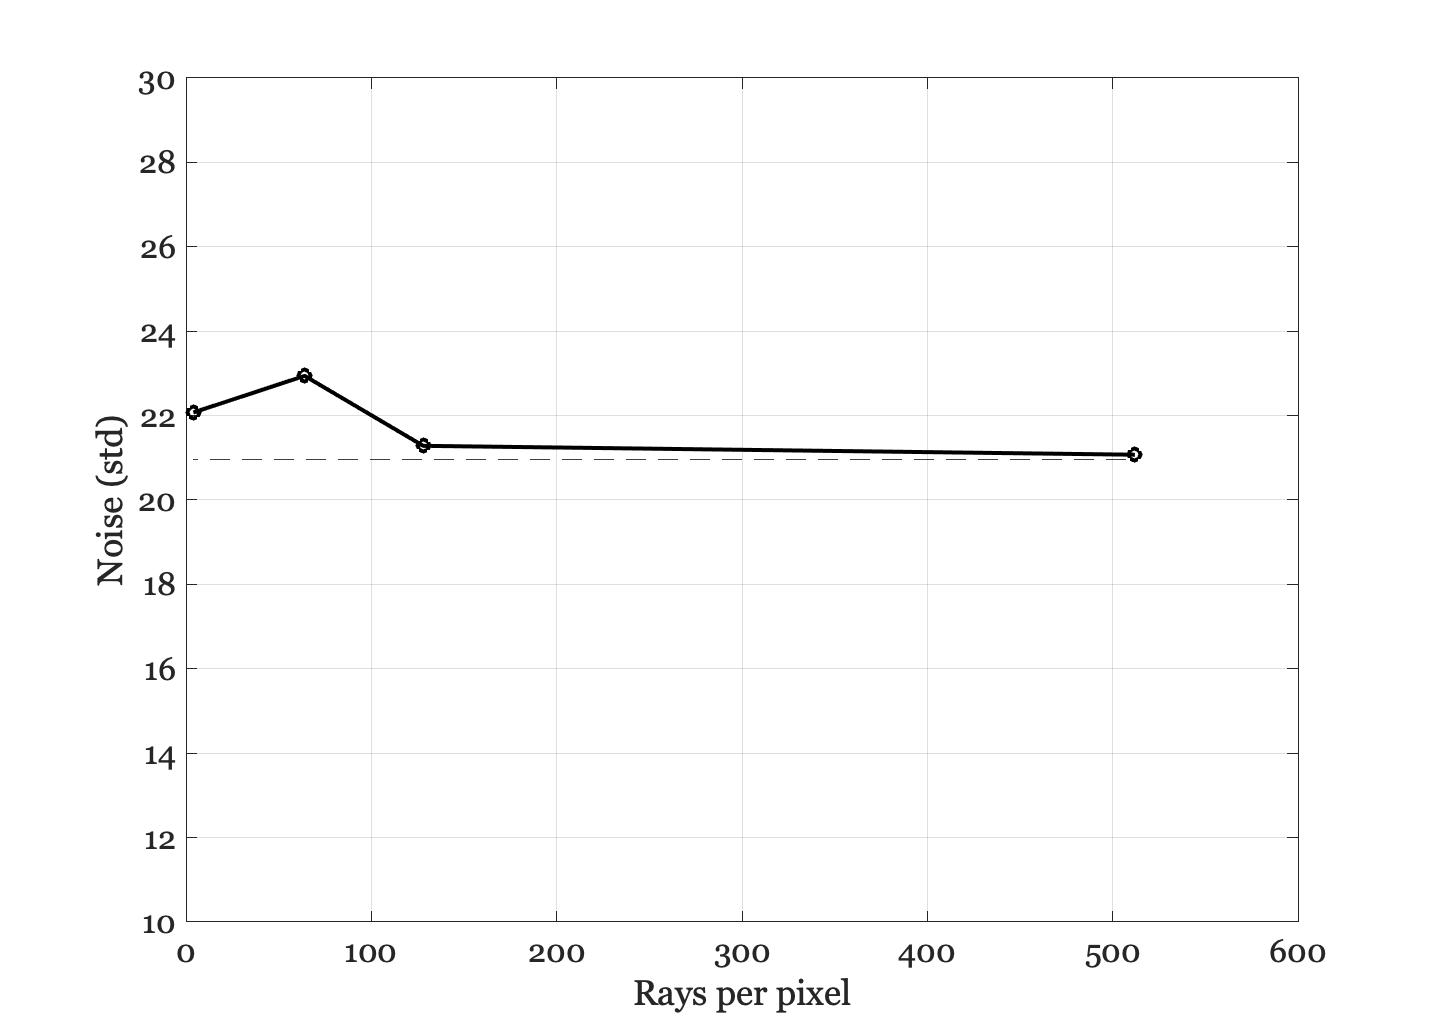


ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise (std)');
ylim([10 30]);

## Flat surface:  lens

The case of a simple double-Gauss lens converges more slowly

rays = [64 128 512 1024];
[rn, pn] = piRenderNoise('rays',rays,'lensname','dgauss.22deg.12.5mm.json');

2.8 micron sensor created
Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface":"/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/renderings/flatSurface.dat /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
*** Rendering time for flatSurface:  9.9 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/

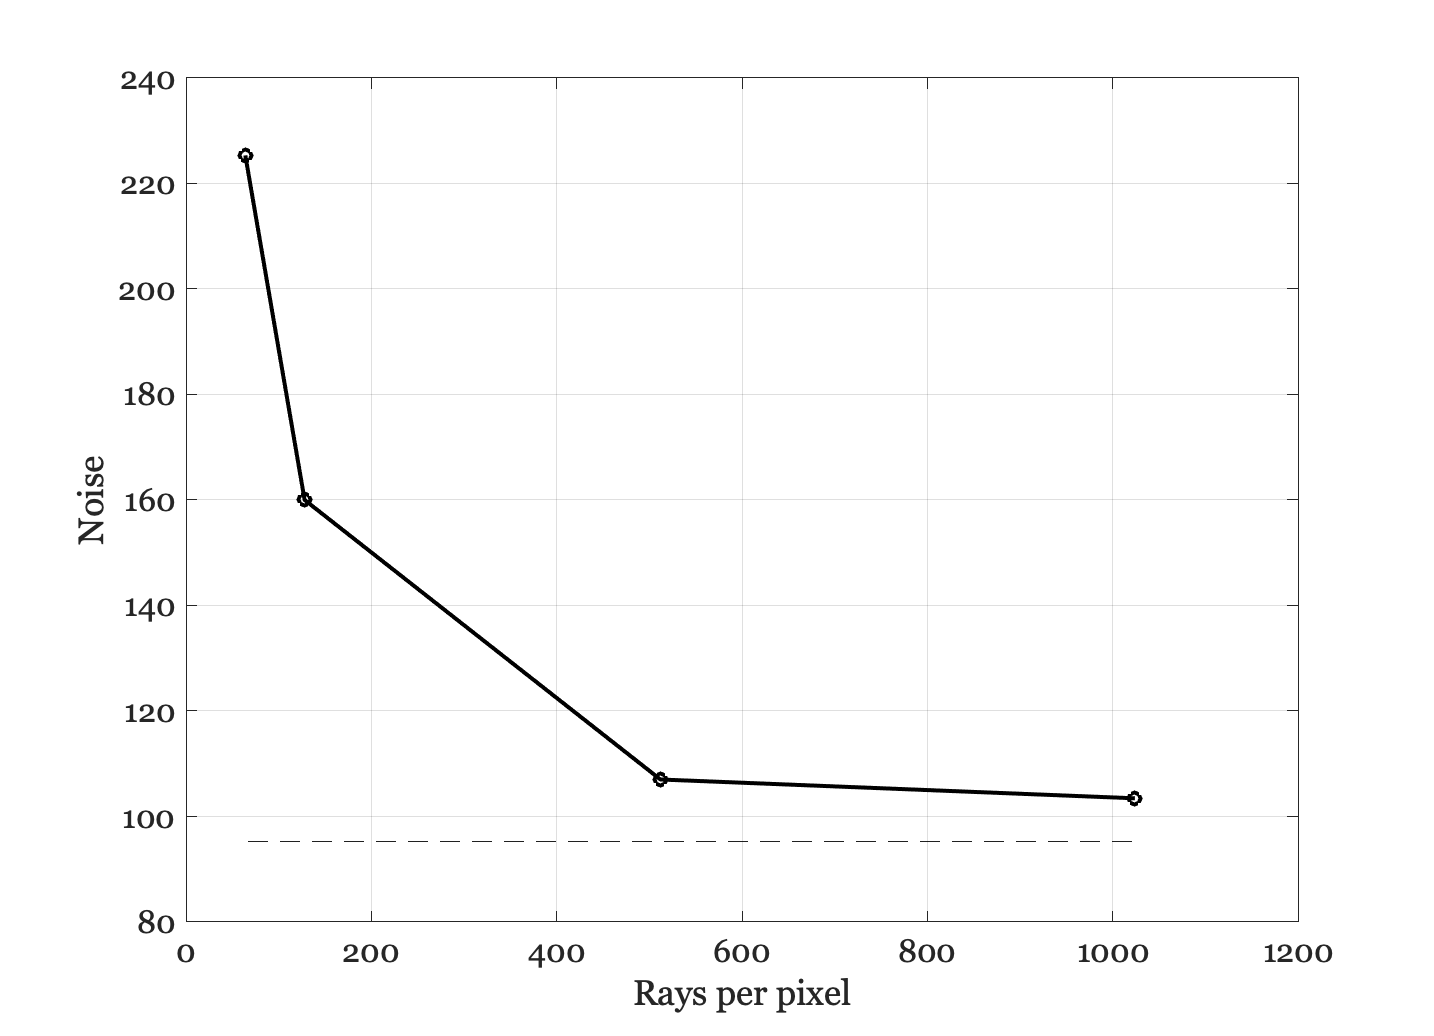


ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise');

## Cornell box:  back surface

The number of bounces becomes relevant for the Cornell box, with its inter-reflections.  We start with the back surface in the middle.  There are not as many inter-reflections there (though some!).  We can try other parts of the scene.

By making a very small film diagonal, we only measure a small part of the image.  But even though it is small, there is probably still some shading that increases the render noise value.

rays = [64 512 1024];
[rn, pn, idealSensor] = piRenderNoise('rays',rays,...
    'scene name','cornell box reference', ...
    'film diagonal',0.15, ...
    'nbounces',1);

2.8 micron sensor created
Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference":"/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  9.8 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:lat

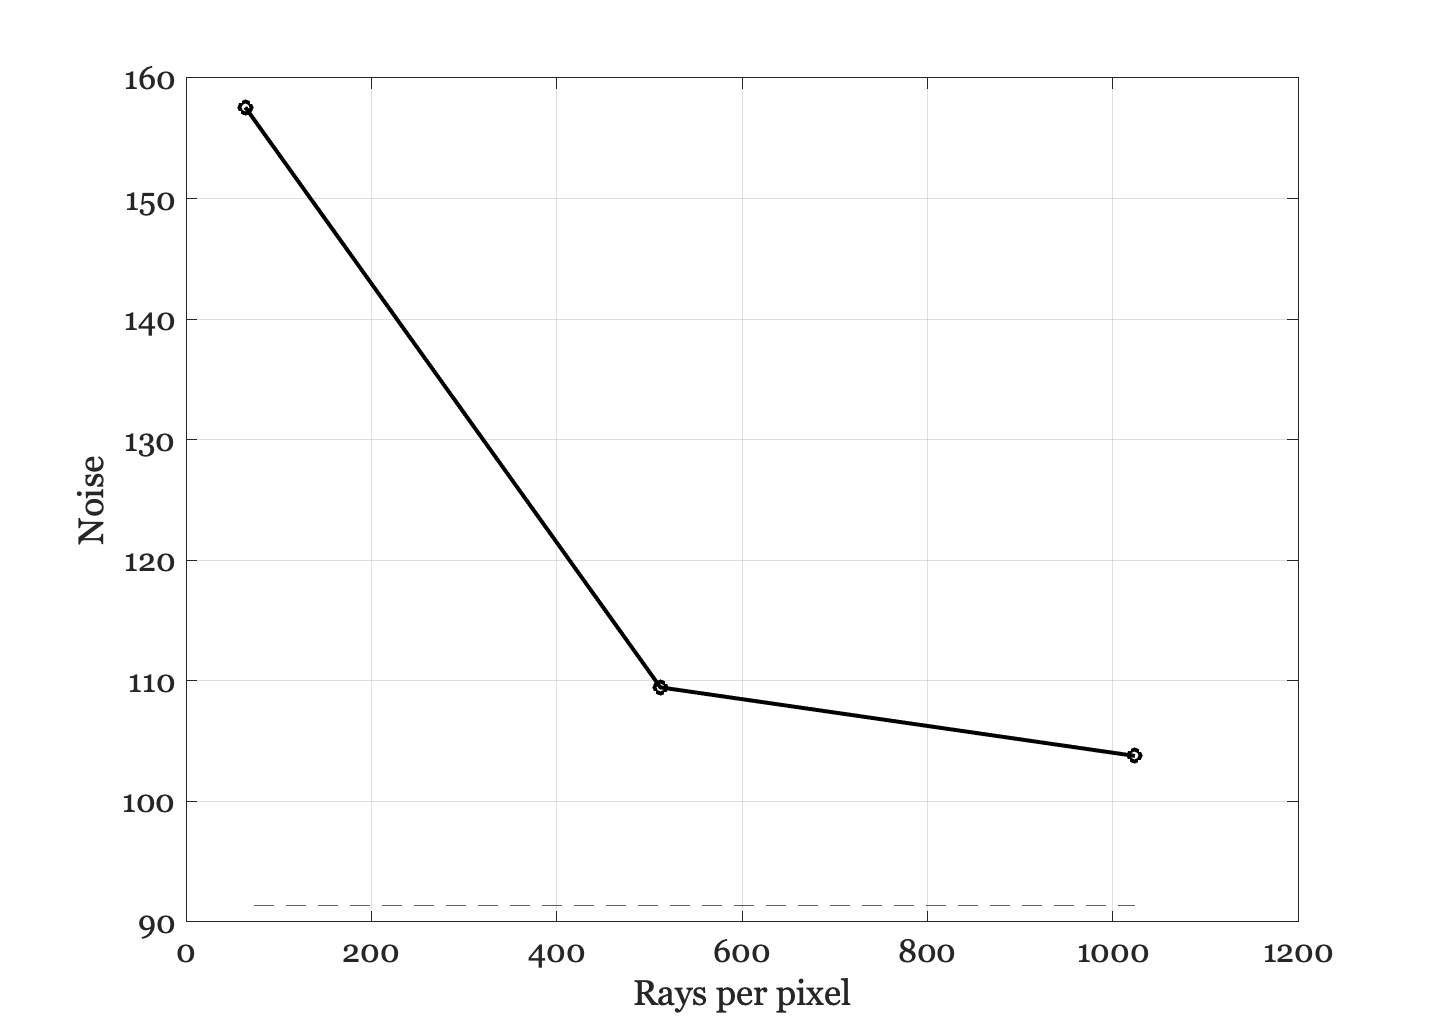


ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise');